# PHSCS 560

## HW: Functions

### Problem 1: Expanding and Interpolating Functions

Part A: Taylor Series Approximation

% anonymous function for Taylor series of sin(x) with N terms
sinTaylor = @(x,N) sum((-1).^((1:N)-1) .* x.^(2*(1:N)-1) ./ factorial(2*(1:N)-1),2);

% create 10^6 randomly distributed points between 0 and 2\pi
xq = 2*pi*rand(1e6,1);

tic
trueResult = sin(xq);
tTrue = toc;

N = [10,100,1000];
for i = 1:length(N)
    tic
    approx = sinTaylor(xq,N(i));
    tTaylor(i) = toc;
    errTaylor(i) = rms(approx - trueResult);
end

Part B: Linear Interpolation

for i = 1:length(N)
    x = linspace(0,2*pi,N(i));
    tic
    approx = linterp(x,sin(x),xq);
    tInterp(i) = toc;
    errInterp(i) = rms(approx - trueResult);
end

rowNames = cell(2*length(N),1);
for i = 1:length(N)
    rowNames{i} = ['Taylor Series, N = ',num2str(N(i))];
    rowNames{i+length(N)} = ['Linear Interp, N = ',num2str(N(i))];
end
colNames = {'RMS Error','Time (s)'};
T = table([errTaylor,errInterp]',[tTaylor,tInterp]','RowNames',rowNames,'VariableNames',colNames)

T = 6×2 table
                               RMS Error     Time (s)
                               __________    ________

    Taylor Series, N = 10      0.00015997    0.51546 
    Taylor Series, N = 100     2.6667e-15     4.2341 
    Taylor Series, N = 1000           NaN     36.262 
    Linear Interp, N = 10         0.03115    0.19719 
    Linear Interp, N = 100     0.00025997     1.0656 
    Linear Interp, N = 1000    2.5538e-06     32.522 


### Problem 2: Numerical Definite Integrals (Quadrature)

#### Part A: Black-Box Integration

I'm using MATLAB's *integraI* function, which uses global adaptive quadrature to do the numerical integration.

f = @(x) exp(-cos(x));              % anonymous function f(x)
g = @(x) f(x) .* (abs(x) <= 1);     % anonymous function g(x), defined piecewise

Ia = [integral(f,-pi,pi),...   % I1
      integral(f,-1,1),...     % I2
      integral(g,-pi,pi)];     % I3

Iexact = [7.9549265210128452745132196653294,...
          0.87070265620795901020832433774759,...
          0.87070265620795901020832433774759];

IaErr = Ia - Iexact

IaErr =   -8.8818e-16  -2.2204e-16  -1.1113e-07


So, we got the first two integrals within machine precision of the decimal approximations. However, the third integral has an error of about 9 orders of magnitude greater than machine precision. So, it looks like the first two converge nicely, while the third is numerically difficult.

#### Part B: Trapezoid Rule and Convergence

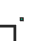

N = 2.^(0:10); % number of points
Ib = zeros(length(N),3); % initialze empty integral result array
for i = 1:length(N)
    Ib(i,:) = [trap(f,linspace(-pi,pi,N(i)+1));...
        trap(f,linspace(-1,1,N(i)+1));...
        trap(g,linspace(-pi,pi,N(i)+1))];
end

% plot result
figure
loglog(N,abs(Ib - Iexact))
xlabel('N')
ylabel('Absolute Relative Error')
grid on
legend('I_1','I_2','I_3')

### Problem 3: Periodic and Spherical Integrals

#### Part A: Optimal Parameters for Periodic Integration

#### Part B: Spherical Integration

### Problem 4: Summing Series

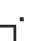

N = 2.^(0:22); % number of points

sinf = pi/4;
for i = 1:length(N)
    sn(i) = s(N(i));
    snp(i) = sAitken(N(i));
end
% plot result
figure
loglog(N,abs(sn - sinf),'DisplayName','s_n')
hold on
loglog(N,abs(snp - sinf),'--','DisplayName','Aitken \Delta^2 s_n''')
hold off
xlabel('N')
ylabel('Absolute Relative Error')
grid on
legend('AutoUpdate','off')
yline(1e-7,':k','LineWidth',1.5,'Label','10^{-7}')
xlim([N(1),N(end)])

So, the standard direct sum routine requires approximately $2\cdot {10}^{6\;}$terms to converge within ${10}^{-7}$. However, Aitken's method only requires roughly 100 terms to achieve this same level of convergence!

### Functions

function yq = linterp(x,y,xq)
    % Linear Interpolation Scheme
    % INPUTS
    %   x - input vector of sample points
    %   y - input vector of function points
    %   xq - vector of query sample points to interpolate to
    % OUTPTS
    %   yq - vector of linearly interpolated function points\

    % enforce column vectors
    x = x(:);
    y = y(:);
    xq = xq(:);
    
    % find indices of two closest points in x for each point in xq
    [~,ind] = sort(abs(x - xq'),1);
    % make sure bounds are ordered from lower to higher
    bounds = sort(ind(1:2,:));
    
    yq = y(bounds(1,:)) + (xq - x(bounds(1,:))) .*...
        (y(bounds(2,:)) - y(bounds(1,:))) ./ ...
        (x(bounds(2,:)) - x(bounds(1,:)));
end

function int = trap(fun,pts)
    dx = pts(2:end) - pts(1:end-1); % spacing between grid points
    int = sum((fun(pts(1:end-1)) + fun(pts(2:end)))/2 .* dx); % trapezoid rule
end

function sn = s(n)
    jj = 0:n;
    sn = sum(((-1).^jj) ./ (2*jj + 1));
end

function snp = sAitken(n)
    sn = s(n);
    sn1 = s(n+1);
    sn2 = s(n+2);

    snp = sn - (sn1 - sn).^2 ./ (sn2 - 2*sn1 + sn);
end